## **Sahan Sulochana Hettiarachchi**

## **180237G**

## **BME**

# **Ensemble Averaging**

**2.1. Signal with multiple measurements**

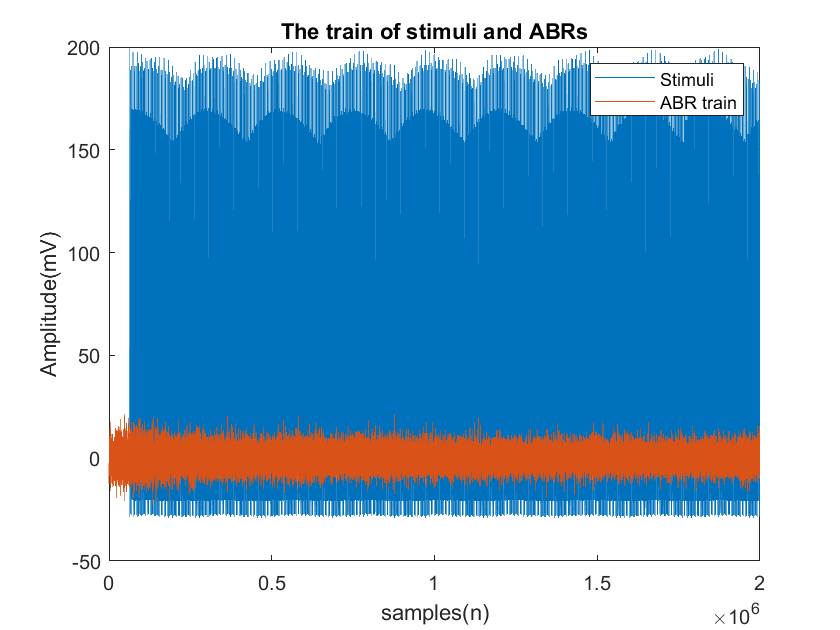

load ABR_rec.mat; 
%plot whole ECG recording with stimuli
figure('Name',"ECG Recording");
plot(ABR_rec);
xlabel('samples(n)');
ylabel('Amplitude(mV)');
title('The train of stimuli and ABRs');
legend('Stimuli','ABR train');

**Zoomed figure**

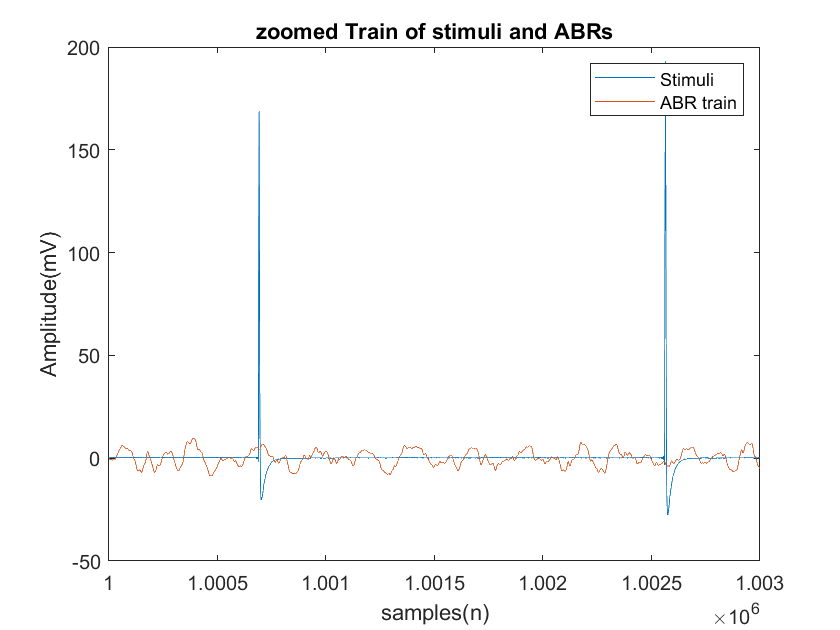

%plot zoomed ECG recording with stimuli
figure;
plot(ABR_rec);
xlabel('samples(n)');
ylabel('Amplitude(mV)');
title('zoomed Train of stimuli and ABRs');
legend('Stimuli','ABR train');
xlim([1000000,1003000]);

thresh = find(ABR_rec(:,1)>50);

Extract actual stimulus points.

j=1;
for i=1:length(thresh)-1
    if thresh(i+1)-thresh(i)>1; stim_point(j,1)=thresh(i+1); j=j+1;
    end
end

Window ABR epochs according to the extracted stimulus points. Consider the window length  to be 12ms (-2ms to 10ms) with reference to the stimulus time point (i.e. -80 to 399 sample  points at fs=40 kHz)

j = 0;
for i=1:length(stim_point) j = j + 1;
epochs(:,j) = ABR_rec((stim_point(i)-80:stim_point(i)+399),2);
end

Calculate the ensemble average of all the extracted epochs.

ensmbl_avg = mean(epochs(:,(1:length(stim_point))),2);

 Plot the ensemble averaged ABR waveform.

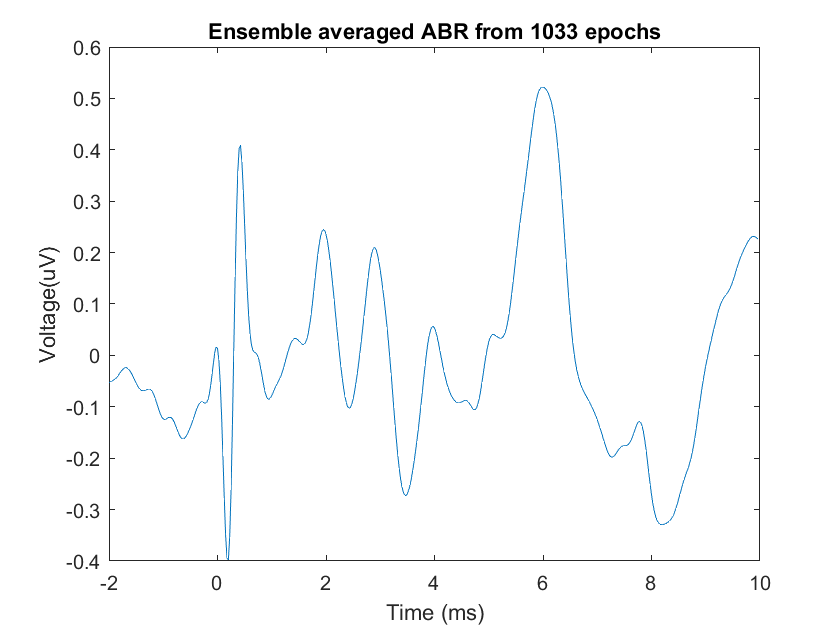

figure,
plot((-80:399)/40,ensmbl_avg)
xlabel('Time (ms)'), ylabel('Voltage(uV)');
title(['Ensemble averaged ABR from ',num2str(length(epochs)),' epochs'])

## **Improvement of the SNR**

MSE calculation

[N,M] = size (epochs);
MSE = zeros(1,M);
for k=1 : M
    yk = mean(epochs(:,1:k),2);
    diff = (ensmbl_avg - yk);
    MSE(k) = sqrt((diff'*diff)/N);
    
    noise = ensmbl_avg - yk;
    SNR(k) = snr(ensmbl_avg,noise);
    
end

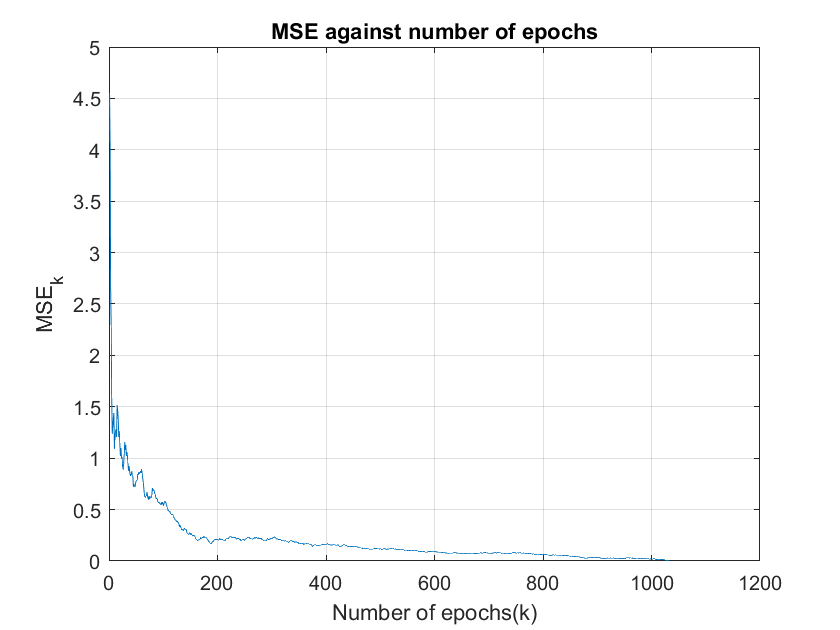

%plot MSE against number of epochs
figure;
plot(1:M,MSE);
xlabel('Number of epochs(k)');
ylabel('MSE_k');
title('MSE against number of epochs');
grid on;

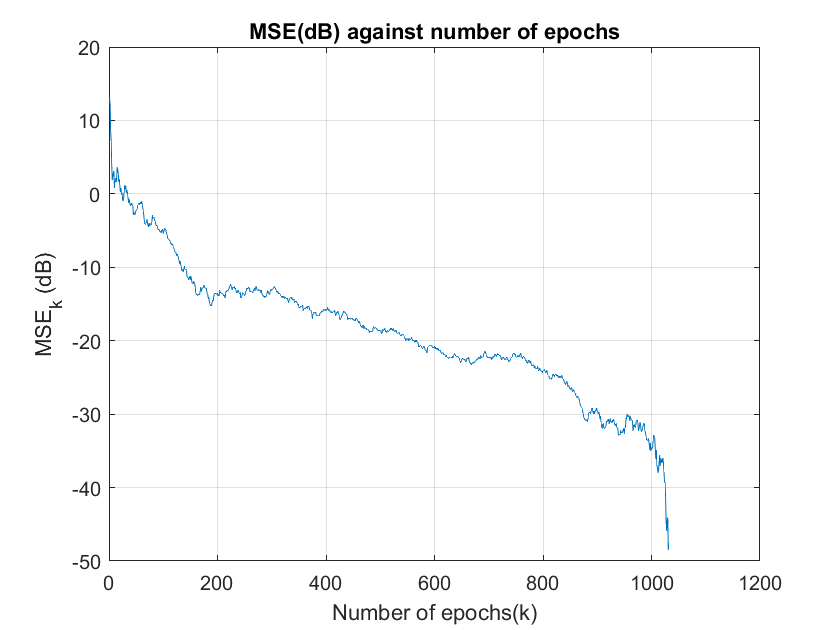

%MSE(dB) against number of epochs
figure;
plot(1:M,20*log10(MSE));
xlabel('Number of epochs(k)');
ylabel('MSE_k (dB)' );
title('MSE(dB) against number of epochs');
grid on;

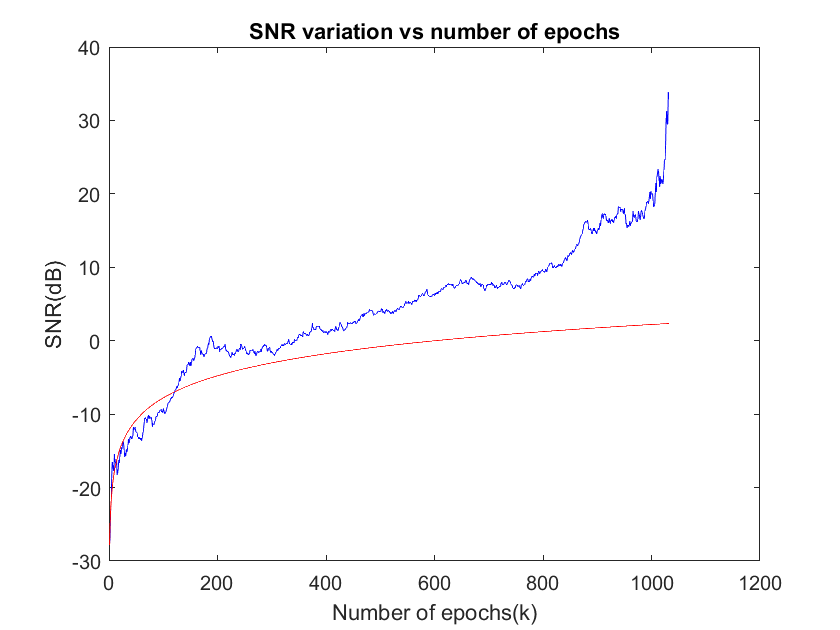

%plot SNR variation vs number of epochs
k= 1 : 1: M;
idealSNR = 10*log10(k)+SNR(1);
plot(k,SNR,'b',k,idealSNR,'r');
xlabel('Number of epochs(k)');
ylabel('SNR(dB)' );
title('SNR variation vs number of epochs');

**2.2. Signal with repetitive patterns**

Clear the work space

clear all; clc;

Load the  ECG_rec.mat file

load  ECG_rec.mat;

Plot the waveform of the  signal

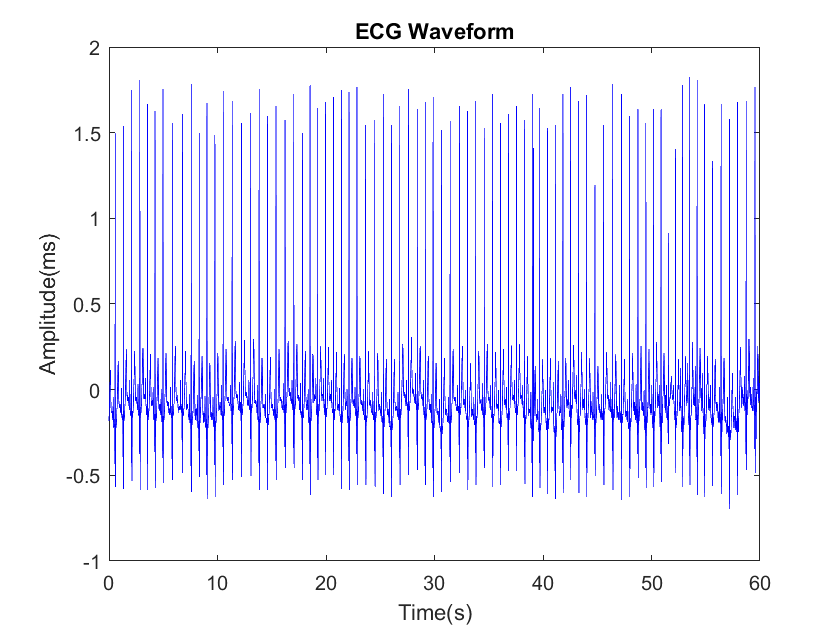

fs = 128; % Sampling frequency
figure;
t = (0:length(ECG_rec)-1)/fs;
plot(t,ECG_rec,'b');
xlabel('Time(s)');
ylabel('Amplitude(ms)' );
title('ECG Waveform');

Obtaining the required figure

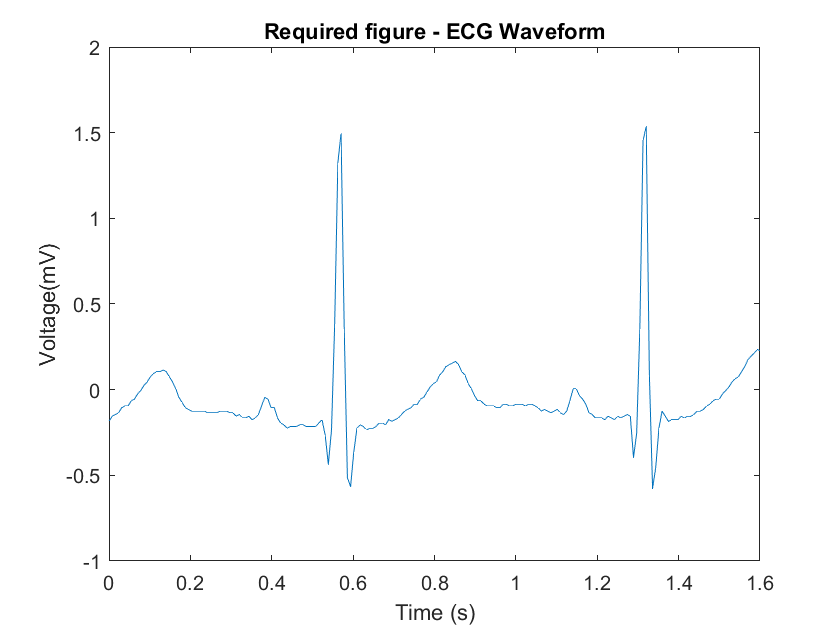

figure
plot(t ,ECG_rec);
hold on
xlim([0,1.6]);
xlabel('Time (s)');
ylabel('Voltage(mV)');
title('Required figure - ECG Waveform');
hold off

Obtaining single PQRST signal

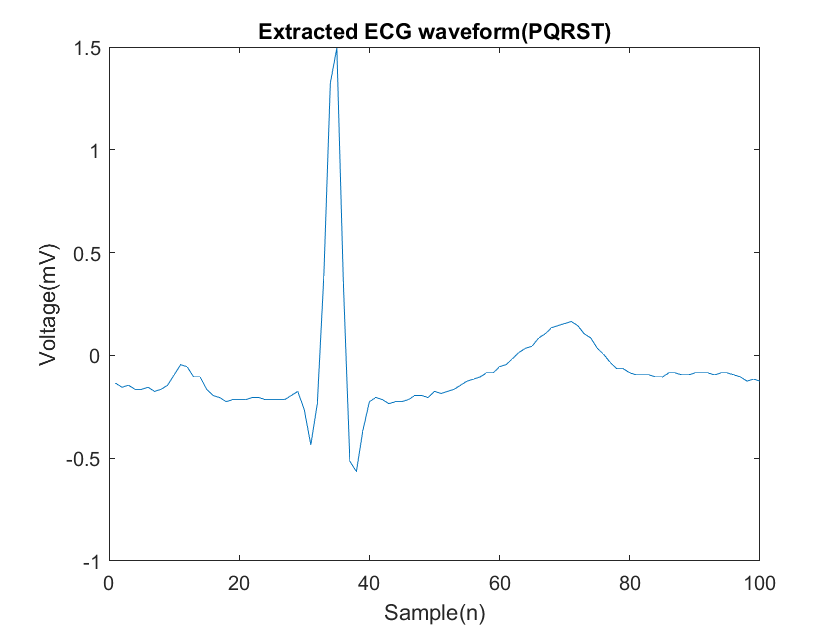

x1= 40;
x2= 139;
ECG_template = ECG_rec(x1:x2);

figure;
plot(1: length(ECG_template) ,ECG_template);
xlabel('Sample(n)');
ylabel('Voltage(mV)');
title('Extracted ECG waveform(PQRST)');

Adding additive white gaussian noise

nECG = awgn(ECG_rec, 5 , 'measured');

Plotting the ECG signal

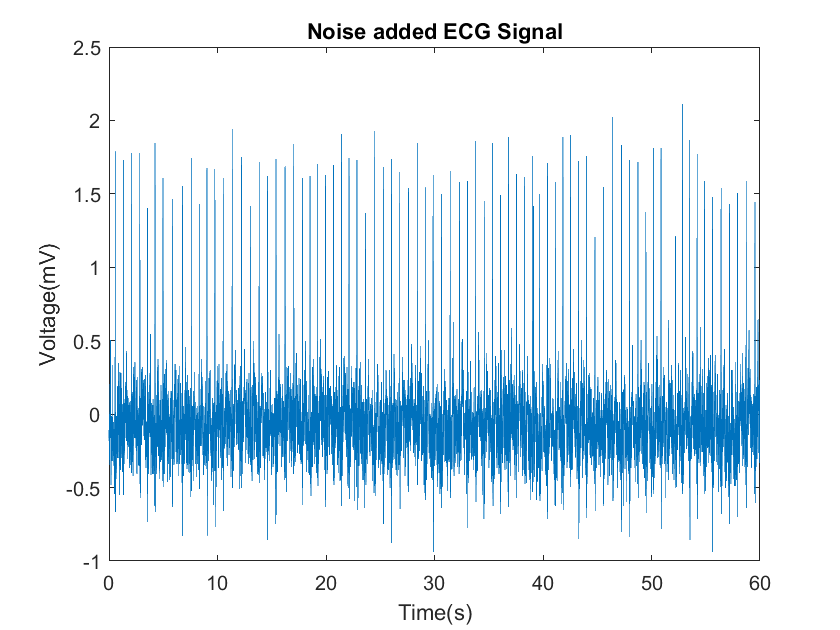

figure;
plot(t ,nECG);
xlabel('Time(s)');
ylabel('Voltage(mV)');
title('Noise added ECG Signal');

**Segmenting ECG into separate epochs and ensemble averaging**

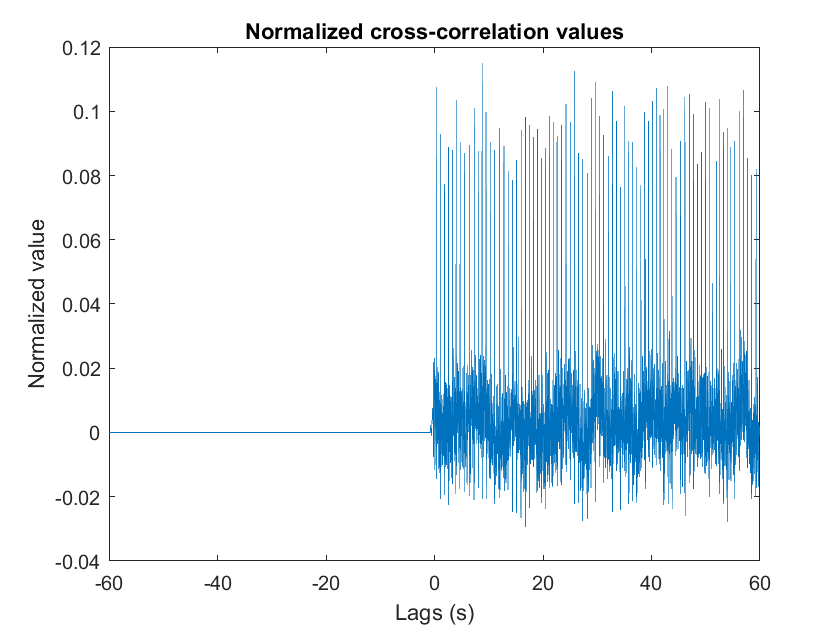

%plot cross corilation values

%Pad adding and rebuilding the ECG template
rebuild_ECG_template = padarray(ECG_template,[0 (length(nECG) -length(ECG_template))] ,0,'post');
[xcorrValues,lags] = xcorr(nECG,rebuild_ECG_template,'coeff');

figure
plot(lags/fs, xcorrValues)
xlabel('Lags (s)');
ylabel('Normalized value');
title('Normalized cross-correlation values');

%Obtaining useful data values 
xcorrUsed = xcorrValues((length(xcorrValues) + 1)/2 : length(xcorrValues));


Let's take the thresshold value as **0.08**

**Obtaining highets correlated points**

thread = 0.08;

%epochs index template generate
epochIndexT = zeros(1,length(xcorrUsed));

i = 1;
k = 1;
while i <=length(xcorrUsed)
    if xcorrUsed(i) > thread
        value = xcorrUsed(i);
        epochIndexT(k) = i;
        for j = 1 : 2
            if xcorrUsed(i+j) > value
                value = xcorrUsed(i+j);
                epochIndexT(k) = i+j;
            end
        end
    k=k+1;
    i= i + 2;
    end
    i=i+1;
end

**Obtaining highets correlated points and epochs**

epochIndexes = epochIndexT(1 : k-1);
epochs = zeros(length(ECG_template) ,k-1);

% Obtaining the epochs related to highest correlation
kNew = 0;
for i = 1:k-1
    if epochIndexes(i) + length(ECG_template) - 1 < length(nECG) %ECG_template==40:139
        epochs(: , i ) = nECG(epochIndexes(i) : epochIndexes(i) + length(ECG_template) - 1);
        kNew= kNew+1;
    end
end
epochs = epochs(:, 1 : kNew );
[N,M] = size(epochs);

SNR calculation

SNR = zeros(1, M);
for k = 1 : M
    yk1 = mean(epochs(:,1:k) , 2);
    SNR(k) = snr(ECG_template' , yk1 -ECG_template');
end

Plotting the SNR with respect to number of pulses (k)

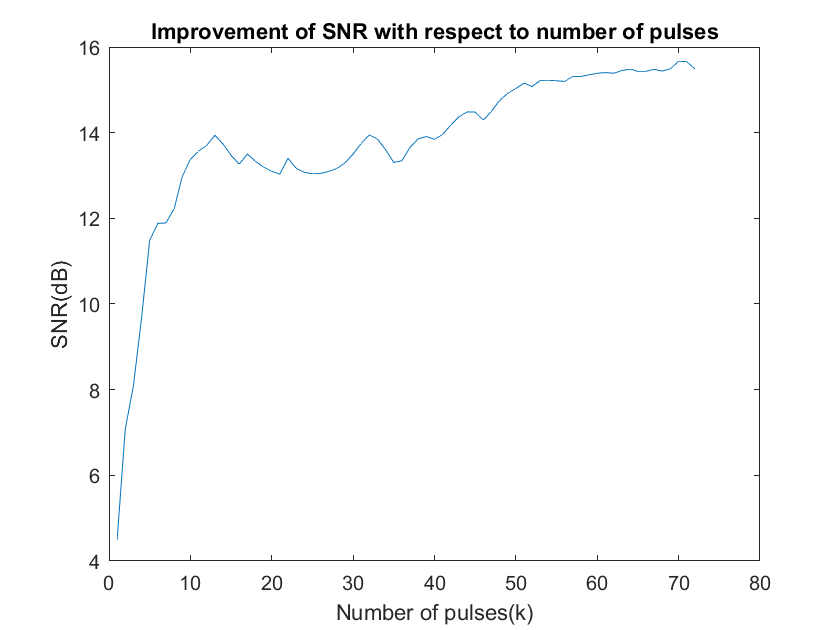

figure;
plot(1:M,SNR);
xlabel('Number of pulses(k)');
ylabel('SNR(dB)');
title('Improvement of SNR with respect to number of pulses');

Calculating ensemble average of arbiitarary two epochs

ensembled1 = mean(epochs(:,1:10) , 2);
ensembled2 = mean(epochs(:,1:50) , 2);

Plotting the SNR

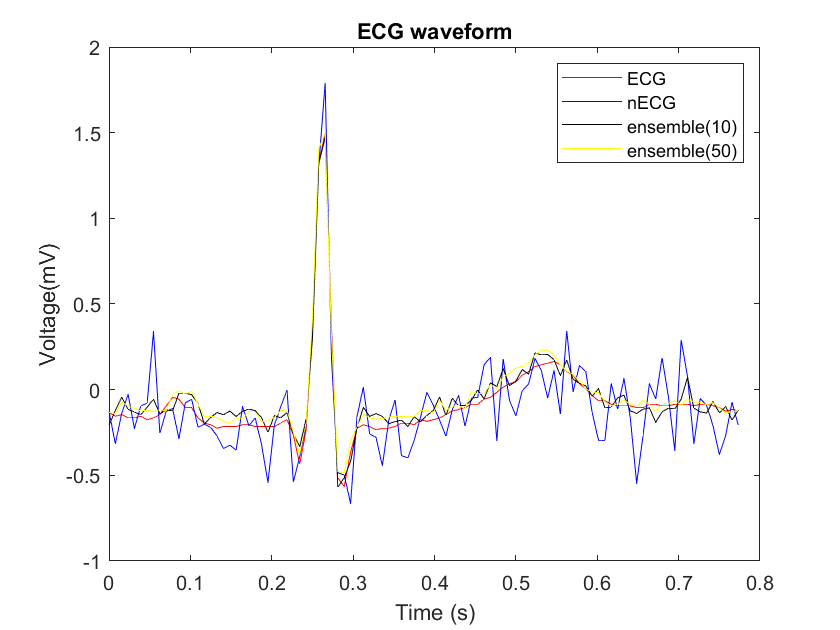


%plot SNR aginst k
t = (0 : length(ECG_template) - 1)/fs;
figure;
plot(t ,ECG_template , 'r' , t ,epochs(:,1), 'b', t ,ensembled1 , 'black' ,t ,ensembled2 , 'y');
xlabel('Time (s)');
ylabel('Voltage(mV)');
title('ECG waveform');   
legend('ECG','nECG','ensemble(10)','ensemble(50)');

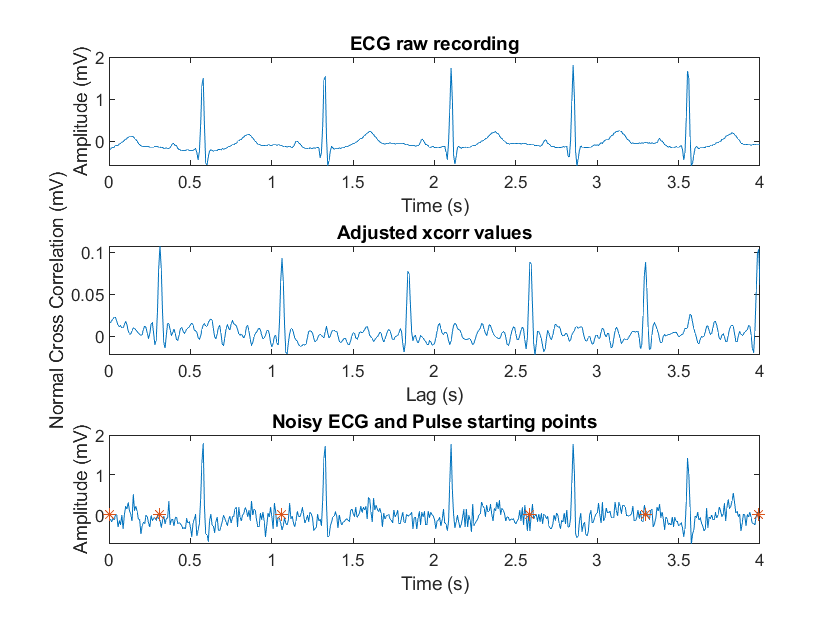

        
%plot points of pulse detection 
len = fs*4;
xAxis = linspace(1.1,len,len)/fs;

%plot portion of ECG recording
figure('Name', 'xcorr pulse detection')
subplot(3,1,1);
plot(xAxis, ECG_rec(1:len))
title('ECG raw recording'),xlabel('Time (s)'), ylabel('Amplitude (mV)')

%plot delay adjusted cross corilation values
subplot(3,1,2);
plot(xAxis, xcorrValues(floor(length(xcorrValues)/2)+1:floor(length(xcorrValues)/2+len)))
title('Adjusted xcorr values'),xlabel('Lag (s)'), ylabel('Normal Cross Correlation (mV)')

%plot noisy ECG with maxmimum cross corr. points
subplot(3,1,3);
plot(xAxis, nECG(1:len)), hold on
plot(epochIndexT(epochIndexT < len)/fs,xcorrValues(epochIndexT < len),'*')
hold off
title('Noisy ECG and Pulse starting points'),xlabel('Time (s)'), ylabel('Amplitude (mV)')